clear all;

filename = 'BRPC0002.CSV'

filename = 'BRPC0002.CSV'

file_folder = "D:\WAVE\pcb calibration 230425\";
M = readmatrix(strcat(file_folder,filename));

mu = 4*pi*10^-7;%[N*A^-2]
a = 0.05;%[m]
R = 0.1;%[Ω]
f = 10000;%[Hz]
n_helm = 10; %[巻き数]



t = [1:500001]

t =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


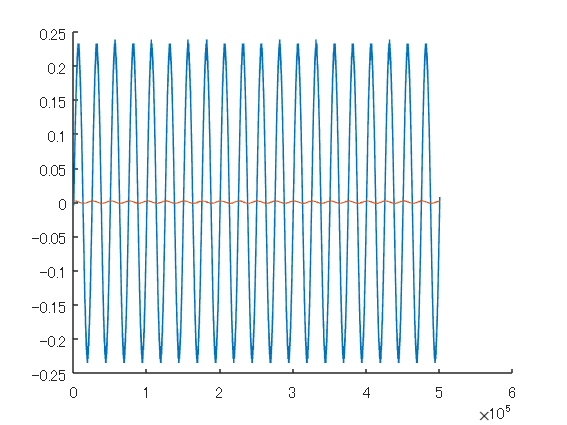

fg = M(:,1)-mean(M(:,1));
coil = M(:,2)-mean(M(:,2));

fg_rms = rms(fg);
coil_rms = rms(coil);
%{
I_rms = ;
B_rms = 0.8^1.5*mu*I_rms/a;


NS = coil_rms/(2*pi*f*B_rms);
%}
%plot
figure;
hold on
plot(t,fg);
plot(t,coil);

function [NS] = NS_calibration(filename)

file_folder = "D:\WAVE\pcb calibration 230425\";
M = readmatrix(strcat(file_folder,filename));

mu = 4*pi*10^-7;%[N*A^-2]
a = 0.05;%[m]
R = 0.1;%[Ω]
f = 10000;%[Hz]
n_helm = 10; %[巻き数]



t = [1:500001]
fg = M(:,1)-mean(M(:,1));
coil = M(:,2)-mean(M(:,2));

fg_rms = rms(fg);
coil_rms = rms(coil);

%{
I_rms = ;
B_rms = 0.8^1.5*mu*I_rms/a;


NS = coil_rms/(2*pi*f*B_rms);
%}

end

